# 数字图像处理 作业6 (4/9)

阮泉源 201930033629

## 图像傅里叶变换

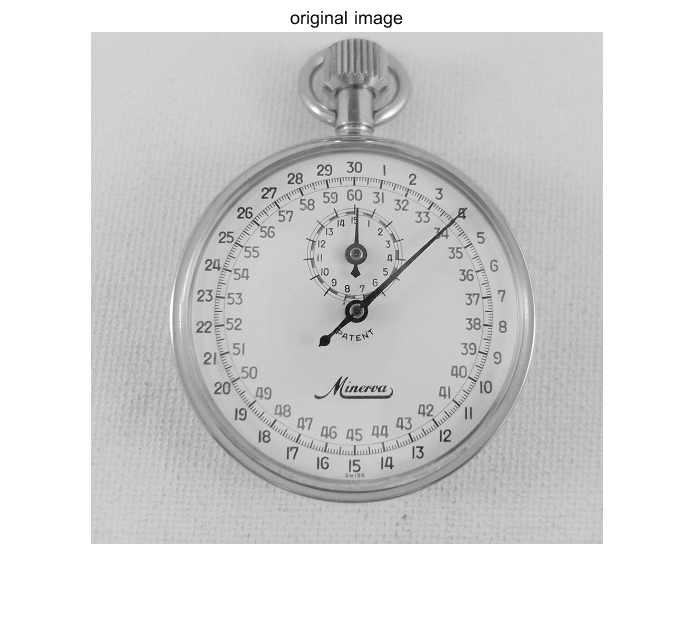

im_watch = imread('watch.jpg');

im_watch = rgb2gray(im_watch);
im_watch = im2double(im_watch);

fft_watch = fft2(im_watch);

figure;
imshow(im_watch)
title('original image')

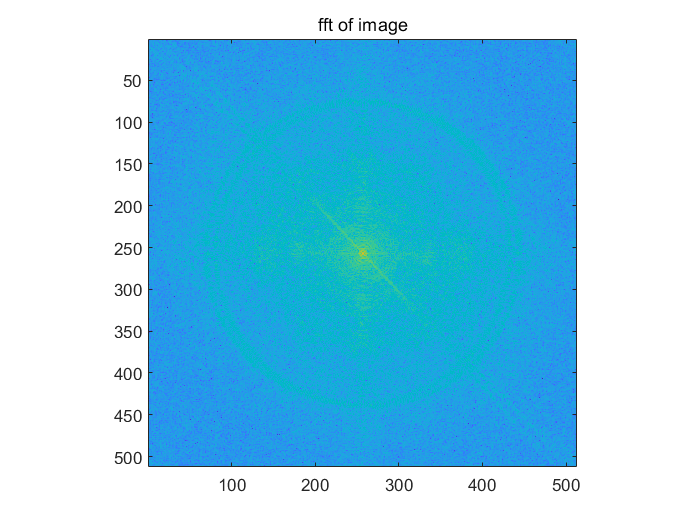

figure;
imagesc(real(log(1+(fftshift(fft_watch)))));
title('fft of image')
axis equal tight

[w, h] = size(fft_watch);

D0 = 25;

[m, n] = meshgrid(0:w-1, 0:h-1);

lpf_mask=((m.^2 + n.^2)<D0^2);
lpf_mask = lpf_mask+fliplr(lpf_mask);
lpf_mask = lpf_mask+flipud(lpf_mask);

fft_watch_lpf = fft_watch.*lpf_mask;

im_watch_lpf=ifft2(fft_watch_lpf);

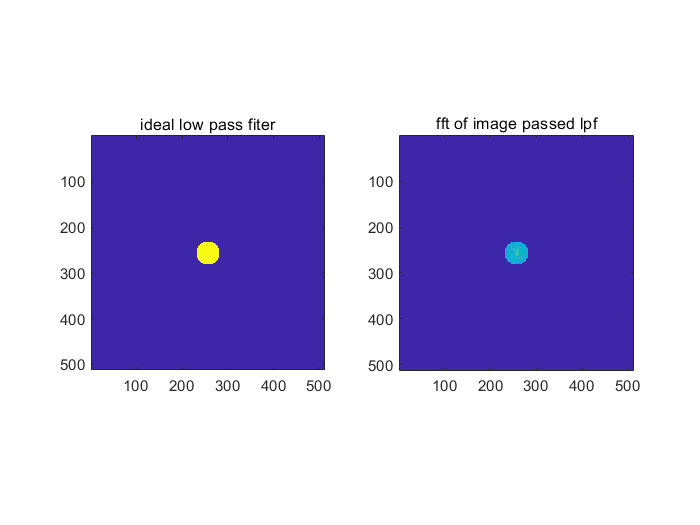

subplot(1,2,1)
imagesc(fftshift(lpf_mask));
title('ideal low pass fiter')
axis equal tight
subplot(1,2,2)
imagesc(real(log(1+(fftshift(fft_watch_lpf)))));
title('fft of image passed lpf')
axis equal tight

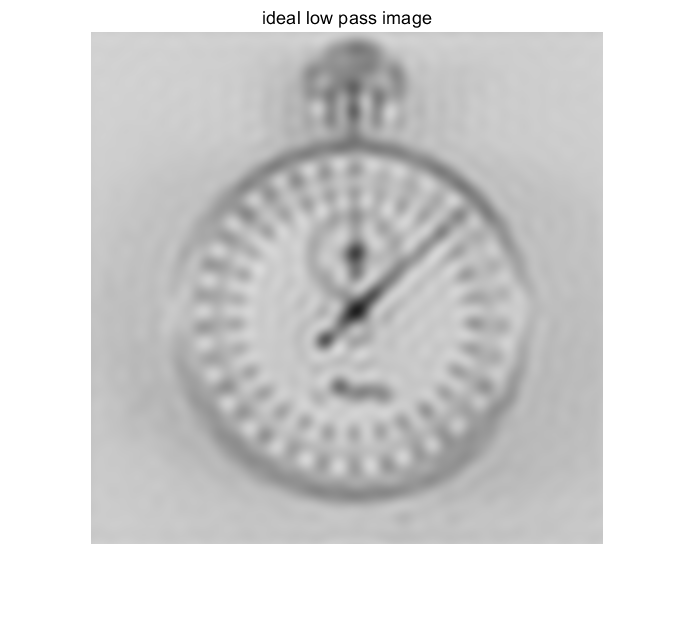

figure;
imshow(real(im_watch_lpf))
title('ideal low pass image')

由于理想低通滤波器的特性，可以看到振铃效应。

hpf_mask = 1-lpf_mask;
fft_watch_hpf = fft_watch.*hpf_mask;

im_watch_hpf=ifft2(fft_watch_hpf);

im_watch_hpf_enhance=ifft2(fft_watch_hpf+fft_watch);

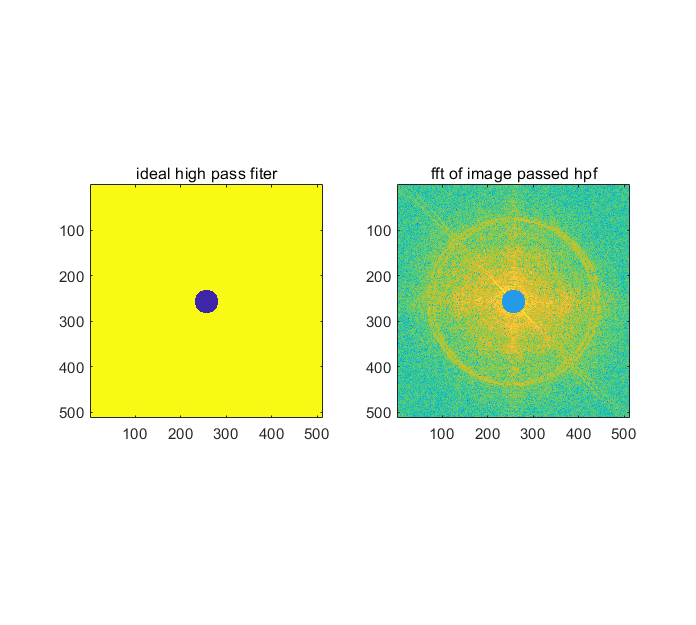

subplot(1,2,1)
imagesc(fftshift(hpf_mask));
title('ideal high pass fiter')
axis equal tight
subplot(1,2,2)
imagesc(real(log(1+(fftshift(fft_watch_hpf)))));
title('fft of image passed hpf')
axis equal tight

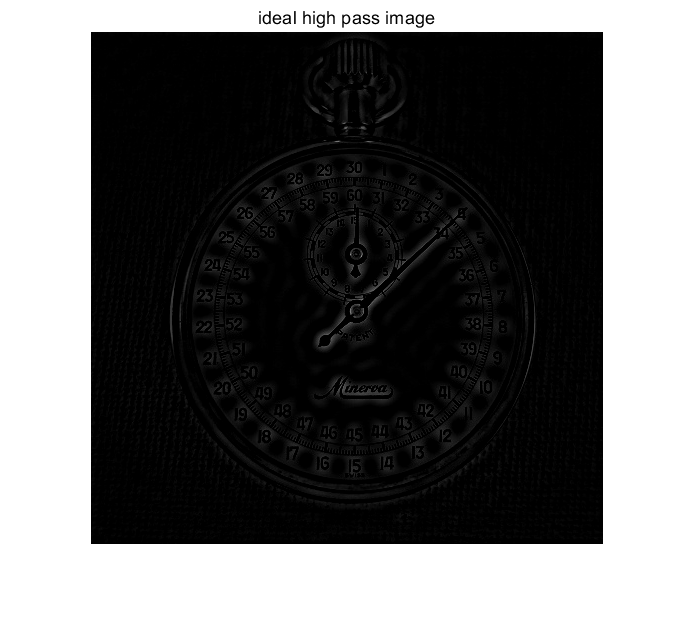

figure;
imshow(real(im_watch_hpf))
title('ideal high pass image')

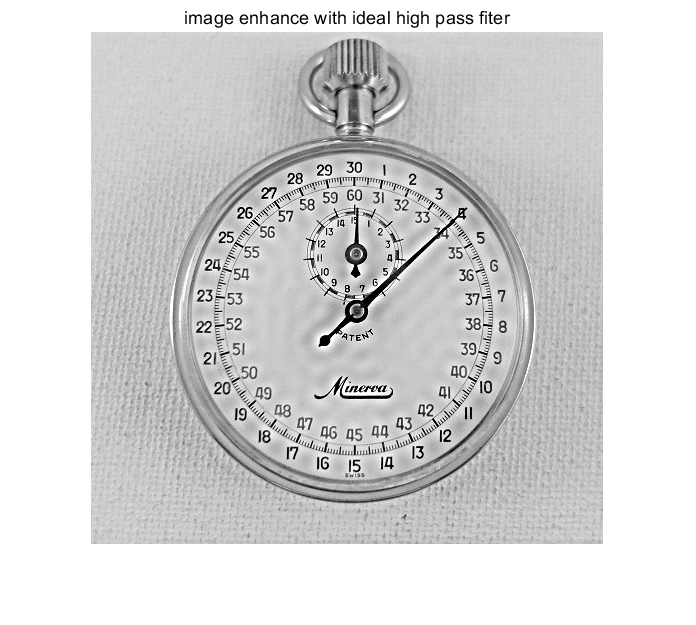

figure;
imshow(real(im_watch_hpf_enhance))
title('image enhance with ideal high pass fiter')

由于理想高通滤波器的特性，可以看到振铃效应。

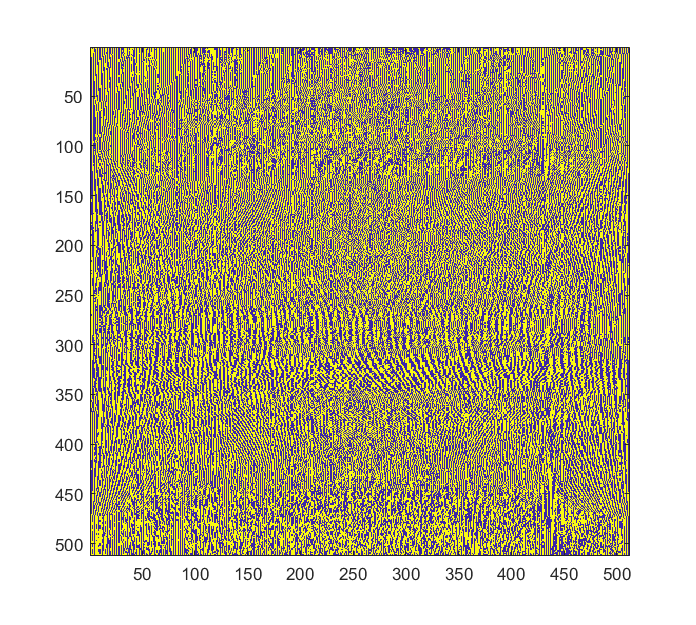

H = -4*(pi^2)*(m.^2+n.^2);
y = fft_watch.*H;
out = ifft(y);
image(real(out))